# Tutorial04 Simulating and Imaging Randomly Diffusing Molecules

#### Notes

Note. Save all my code. They will be reused and build on each other.

Objective: To be more famiiar with Matrix multiplications through a variation of a random walk.

2. Simulating a Random Walk in 1D

1.. Initialize two matrices

% Parameters
L = 500

L = 500

n_particle = 500

n_particle = 500

n_kicks = 10000

n_kicks = 10000


f = zeros(n_kicks, n_particle);
x = zeros(n_kicks, n_particle);

2.. Assign the initial particle positions in f(1, :) such that the n_p particles are uniformly disributed across the Universe.

% Initially did
% f(1,:) = length*rand(1, n_particle)

% After reaching step 5, for convenience, decided to refer to the solution.
f(1,:) = randperm(L)

f =    100   236   317   479   406   161    17   107   496   435   345   158   350   281   169   261   270   498   335   334   251   310    95    63   417   187    90   470   269   197   253   454   181    50   265   376    78   323   382   290   374   294   159   135    94   114   155   250   232   237
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

3.. Store displacement of each kick.

Received help from solution doc.

% Assign kicks at each time step.
f(2:end,:) = randn(n_kicks-1, n_particle)

f =   100.0000  236.0000  317.0000  479.0000  406.0000  161.0000   17.0000  107.0000  496.0000  435.0000  345.0000  158.0000  350.0000  281.0000  169.0000  261.0000  270.0000  498.0000  335.0000  334.0000  251.0000  310.0000   95.0000   63.0000  417.0000  187.0000   90.0000  470.0000  269.0000  197.0000  253.0000  454.0000  181.0000   50.0000  265.0000  376.0000   78.0000  323.0000  382.0000  290.0000  374.0000  294.0000  159.0000  135.0000   94.0000  114.0000  155.0000  250.0000  232.0000  237.0000
   -1.0006   -0.1667    0.1498   -0.3126   -0.2953    0.8561   -0.4030    0.0928   -0.9641   -0.3623    2.1122   -1.3384    0.3576    0.3684    0.5157   -0.5082    0.1601   -0.2445   -1.2919    1.1990    0.9730    0.3098   -0.0044   -0.2539   -0.2716    0.3302   -0.4471   -0.6017    0.4688   -0.0595    1.1836    2.5810   -0.4177    1.2414    0.2861    0.4369   -0.6190   -0.6879   -0.5089   -1.3734    1.4108    1.7273    1.8009   -0.1759   -0.7363   -2.0005   -0.2486   -0.6148   -0.5941   -0

Note. Difference between **rand** and **randn**.

**rand**: uniformly distributed random numbers. Returns random #s between 0 and 1 from uniform distribution.

**randn**: normally(Gaussian) distributed random numbers. Returns random #s of mean 0 and variance 1.

4.. Assign x to the particle trajectories. Use **cumsum** and mod.

% help cumsum
% stepx = cumsum(-1+2*stepx)
x = cumsum(f)

x =   100.0000  236.0000  317.0000  479.0000  406.0000  161.0000   17.0000  107.0000  496.0000  435.0000  345.0000  158.0000  350.0000  281.0000  169.0000  261.0000  270.0000  498.0000  335.0000  334.0000  251.0000  310.0000   95.0000   63.0000  417.0000  187.0000   90.0000  470.0000  269.0000  197.0000  253.0000  454.0000  181.0000   50.0000  265.0000  376.0000   78.0000  323.0000  382.0000  290.0000  374.0000  294.0000  159.0000  135.0000   94.0000  114.0000  155.0000  250.0000  232.0000  237.0000
   98.9994  235.8333  317.1498  478.6874  405.7047  161.8561   16.5970  107.0928  495.0359  434.6377  347.1122  156.6616  350.3576  281.3684  169.5157  260.4918  270.1601  497.7555  333.7081  335.1990  251.9730  310.3098   94.9956   62.7461  416.7284  187.3302   89.5529  469.3983  269.4688  196.9405  254.1836  456.5810  180.5823   51.2414  265.2861  376.4369   77.3810  322.3121  381.4911  288.6266  375.4108  295.7273  160.8009  134.8241   93.2637  111.9995  154.7514  249.3852  231.4059  236

x = mod(x, 500)

x =   100.0000  236.0000  317.0000  479.0000  406.0000  161.0000   17.0000  107.0000  496.0000  435.0000  345.0000  158.0000  350.0000  281.0000  169.0000  261.0000  270.0000  498.0000  335.0000  334.0000  251.0000  310.0000   95.0000   63.0000  417.0000  187.0000   90.0000  470.0000  269.0000  197.0000  253.0000  454.0000  181.0000   50.0000  265.0000  376.0000   78.0000  323.0000  382.0000  290.0000  374.0000  294.0000  159.0000  135.0000   94.0000  114.0000  155.0000  250.0000  232.0000  237.0000
   98.9994  235.8333  317.1498  478.6874  405.7047  161.8561   16.5970  107.0928  495.0359  434.6377  347.1122  156.6616  350.3576  281.3684  169.5157  260.4918  270.1601  497.7555  333.7081  335.1990  251.9730  310.3098   94.9956   62.7461  416.7284  187.3302   89.5529  469.3983  269.4688  196.9405  254.1836  456.5810  180.5823   51.2414  265.2861  376.4369   77.3810  322.3121  381.4911  288.6266  375.4108  295.7273  160.8009  134.8241   93.2637  111.9995  154.7514  249.3852  231.4059  236

**cumsum**: cumulative sum of elements. Check documentation how it works for a matrix.

Sample Code

`Cumsum of each column`

`A = [1 4 7; 2 5 8; 3 6 9]`

`A = `*3×3*

`     1     4     7`

`     2     5     8`

`     3     6     9`

`B = cumsum(A)`

`B = ``3×3`

`     1     4     7`

`     3     9    15`

`     6    15    24`

`Cumsum of each row`

`A = [1 3 5; 2 4 6]`

`A = ``2×3`

`     1     3     5`

`     2     4     6`

`B = cumsum(A,2)`

`B = ``2×3`

`     1     4     9`

`     2     6    12`

**mod**: Takes mod. 

Sample code.

q = [0:10] 

mod(q,5)

mod(q,4)

Q = [0:10;0:10;0:10] 

mod(Q,5) 

mod(Q,2)

Here, mod is used to ensure the particles stay in the universe.

5.. Visualizing particle trajectories by creating an *image*.

I(x,t). corresponds to the # of particles at location x at time t. 

Image: a matrix that represents the grid of pixels, whose entires contain some info about those pixels - here, it's intensity. c.f. The higher the count of a pixel, the brighter it'll be.

% first, use ceiling to discretize x.
x = ceil(x)

x =    100   236   317   479   406   161    17   107   496   435   345   158   350   281   169   261   270   498   335   334   251   310    95    63   417   187    90   470   269   197   253   454   181    50   265   376    78   323   382   290   374   294   159   135    94   114   155   250   232   237
    99   236   318   479   406   162    17   108   496   435   348   157   351   282   170   261   271   498   334   336   252   311    95    63   417   188    90   470   270   197   255   457   181    52   266   377    78   323   382   289   376   296   161   135    94   112   155   250   232   237
   100   238   318   478   406   162    19   108   496   432   349   159   352   282   169   262   270   497   333   336   252   311    97    63   416   188    91   471   271   197   253   457   181    52   268   378    78   325   381   289   376   297   162   133    95   112   156   251   232   236
   100   239   317   479   406   162    20   108   496   431   348   161   352   281   169   


% create image to store result.
% initialize image
I = zeros(L, n_kicks)

I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


% for each number from 1 to 500, count the occurence and store in the matrix.
for n = 1:n_kicks
    location_ranges = 1:500;
    [counts, ind] = histc(x(n, :), location_ranges);
    % transpose(counts)
    I(:, n) = transpose(counts);  % can use " counts.' "
end


% Below is an alternative from sample solution.
% Create the image I(x,t) by counting the # of particles at each time
% at all positions using hist.
%for n = 1:n_kicks  % correct
%    I(:, n) = hist(x(n, :), n_particle);
%end

I

I =      1     2     3     1     1     1     1     4     1     4     1     2     1     5     2     3     3     1     2     0     1     2     2     0     1     2     1     1     0     3     2     0     0     0     1     1     0     1     0     0     1     2     1     2     0     1     3     1     0     1
     1     2     1     2     3     3     2     3     3     0     0     0     2     0     2     2     2     2     1     1     1     0     1     1     3     2     2     2     4     1     2     2     3     1     1     0     0     0     1     1     0     0     1     0     2     1     0     1     0     0
     1     2     1     1     2     1     1     1     0     0     2     1     1     2     3     1     2     1     1     2     2     2     1     1     0     0     4     2     2     1     1     1     1     2     0     2     1     0     1     0     0     0     1     1     0     0     0     1     1     1
     1     0     2     1     0     0     1     1     2     1     2     0     1     1     1   

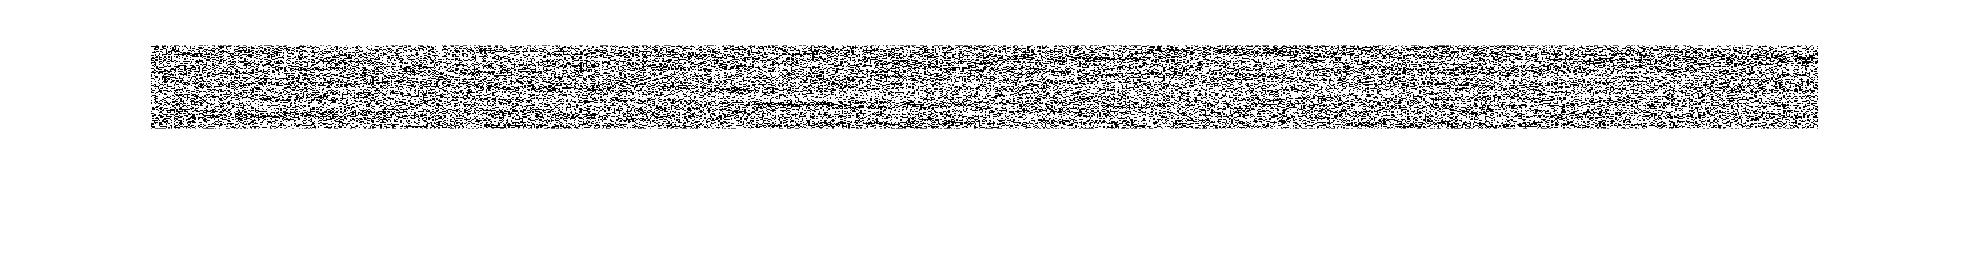

%groupcounts(x)

imshow(I)

Choosing subsection of the matrix and showing it.

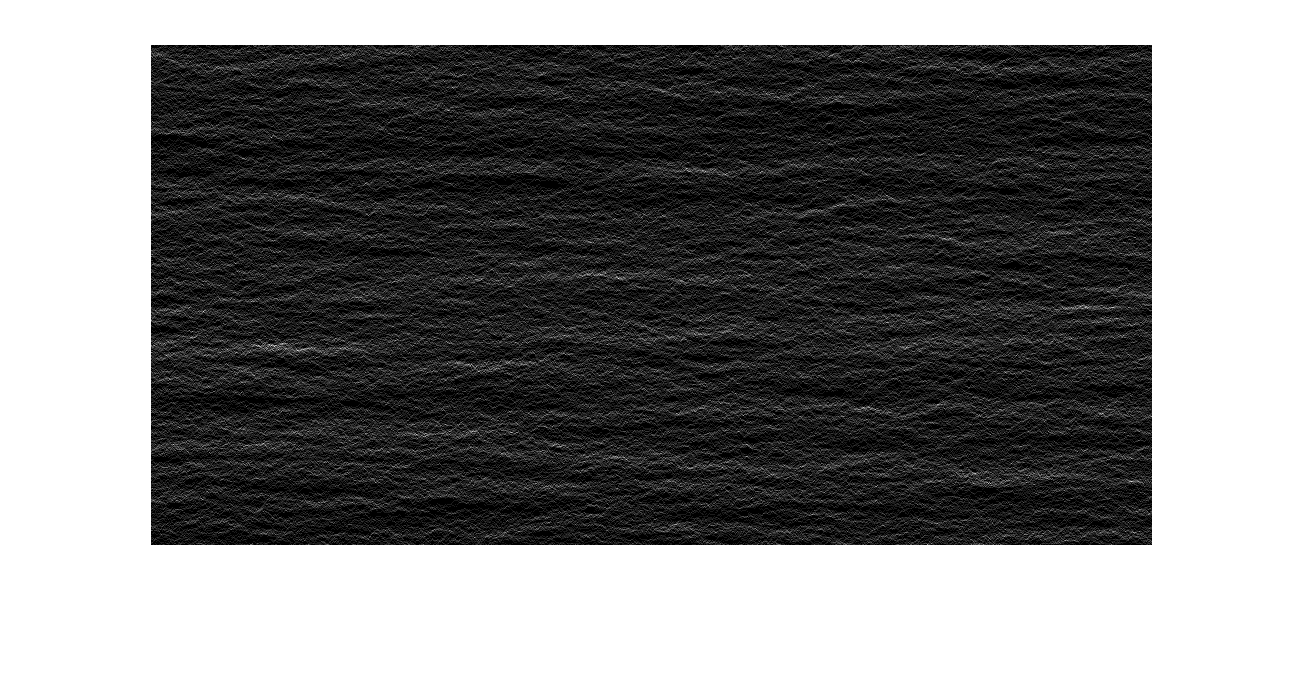

%figure
%I_section = I(:, 4500:5500,[])
% Correction comment: my initial range was 3:950, which was too wide.
imshow(I(:,4500:5500),[])

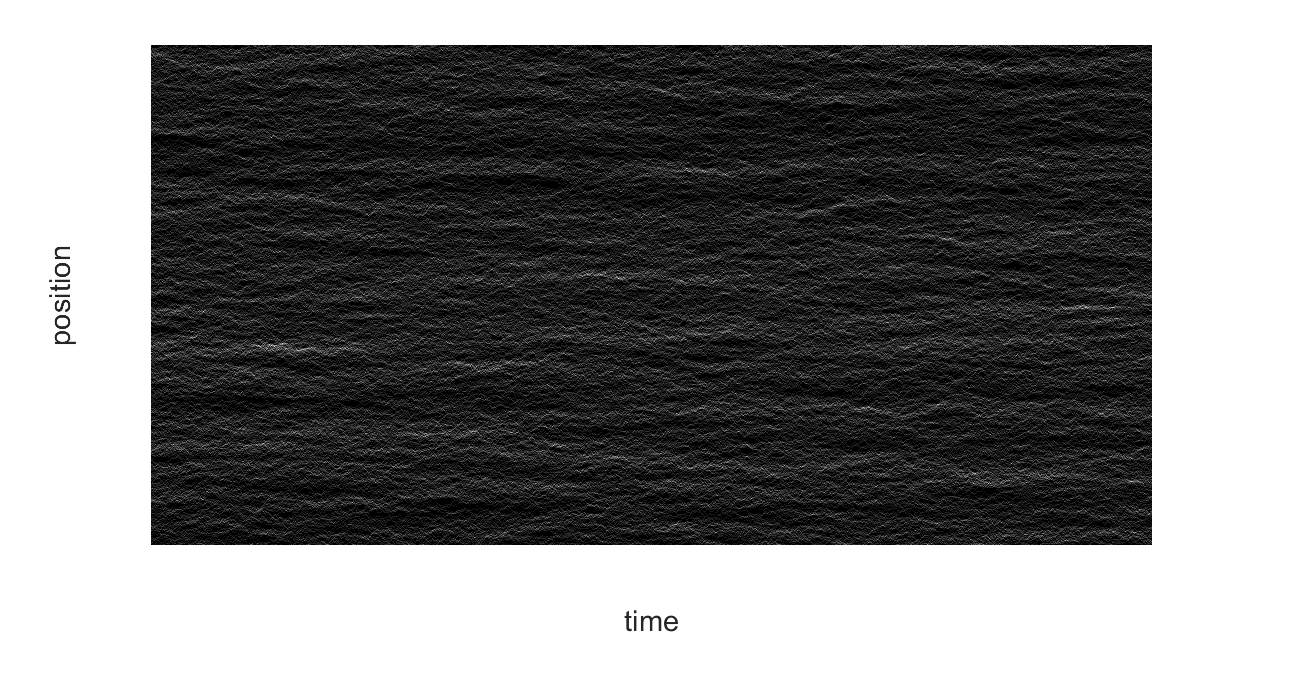


figure % create figure window
imshow(I(:,4500:5500),[]);
xlabel(['time']),ylabel(['position']) 

6.. Calculate the variance in positions sampled by each particle.

% var_particles = var(transpose(I))

% Correction:
variance_x = zeros(1, n_particle)

variance_x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:n_particle
    variance_x(i) = var(x(:, i));
end

% Avg value for variance over all particles:
avg_variance = mean(variance_x)

avg_variance = 8.9206e+03

Correction/Solution: Expected variance is n_kicksd*variance for 1 step = 10000*1 = 10000. This is pretty close to the calculated value.

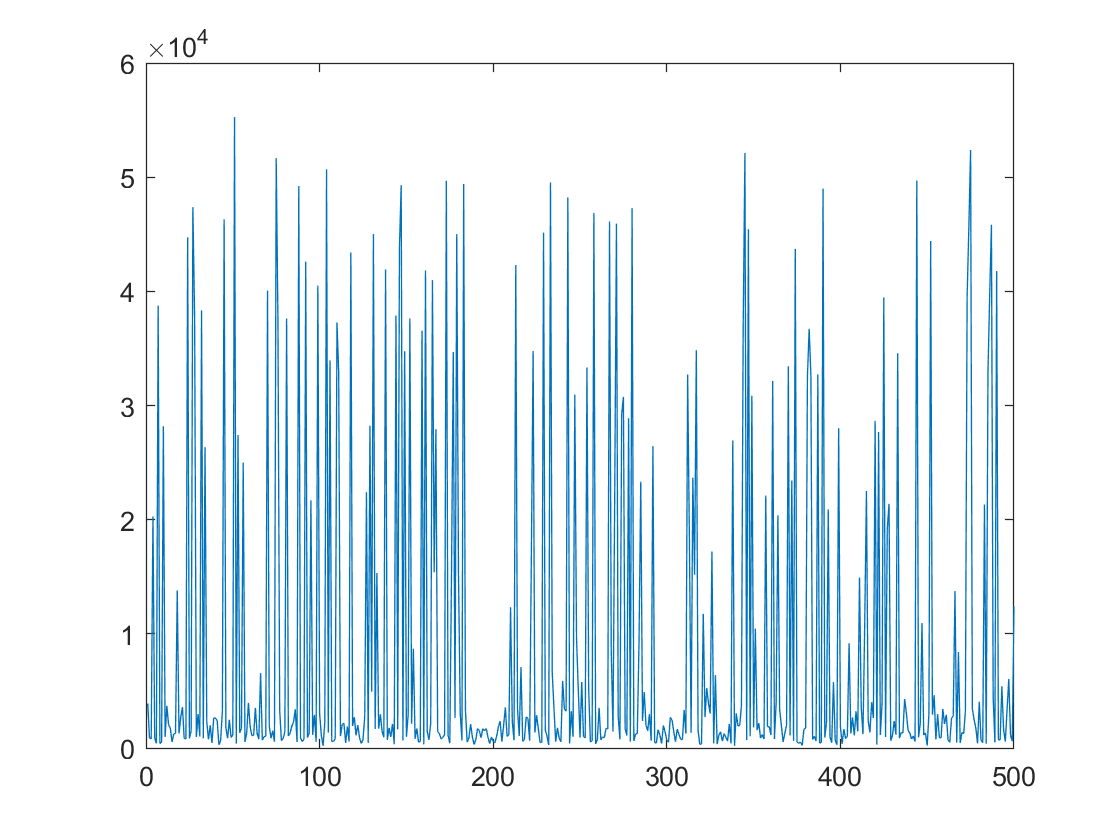

% Plot particle # vs variance
figure
plot(1:n_particle, variance_x);

% xlabel(['Particle number']),ylabel(['Variance']); 


7. Define the deffusion coefficient as D = var/(2*N_kicks). Calculate D.

D = avg_variance/(2*n_kicks)

D = 0.4460

Correction/Solution: Expected value based on expected avg_variance would be 10000/(2*10000) = 0.5. The result was D = 0.4718, so they are pretty close.

`8.. Calculate, approximately, how many pixels - h - will a protein molecule diffusion (in 2D) in a given camera exposure time of 2ms/frame.`

% 100um^2/s * (1 pixel/ 0.4um) * (2 ms / frame)
% 2ms = 2000
h = 100*(1/0.4)*2000

h = 500000

Answer: 500000 pixels.

`Correction: Did not know that protein diffuses according to r^2 = 4Dt.`

`r is the distance diffused (in um in our case.)`

D = 100; % um^2/s, diffusion coefficient.
dx = 0.4; % um/pixel, magnification.
exposureTime = 0.002 % seconds

exposureTime = 0.0020


r = sqrt(4*D*exposureTime); % um. Using r^2 = 4Dt. 
numPixls = r/dx; % result: numPixels = 2.2361